clear
clc

system("make main -f .\Makefile");

make: Nothing to be done for 'main'.



ind = 1;
N_range = 100:50:2500;
for N = N_range
    tic;
    M_range(ind) = system(".\FiniteDifferences.exe " + string(N)); %#ok
    T(ind) = toc; %#ok
    
    v1.x = round((131.25)/400 * N);
    v1.y = round((125)/250 * M_range(ind));
    v2.x = round((400-131.25)/400 * N);
    v2.y = round((125)/250 * M_range(ind));
    
    v3.x = round((151.39)/400 * N);
    v3.y = round((250 - 76.39)/250 * M_range(ind));
    v4.x = round((400 - 151.39)/400 * N);
    v4.y = round((76.39)/250 * M_range(ind));
    
    x = load(".\x.txt");
 
    %DV(ind) = abs(phi(v1.y,v1.x) - phi(v2.y,v2.x));
    DV1(ind) = abs(x(v1.x + N * (v1.y - 1)) - x(v2.x + N * (v2.y - 1))); %#ok [V]
    DV2(ind) = abs(x(v3.x + N * (v3.y - 1)) - x(v4.x + N * (v4.y - 1))); %#ok [V]
    ind = ind + 1;
end

save("validation.mat")

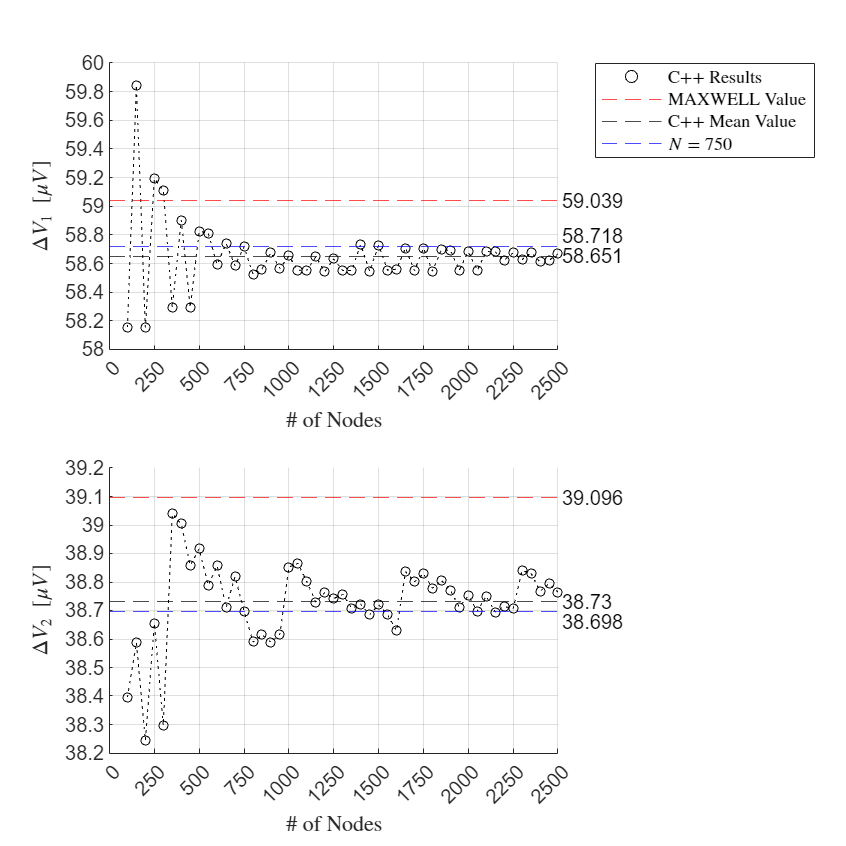

load("validation.mat")
DV_th_1 = 59.039271155962;
DV_th_2 = 39.096156651770;
N_chosen = 750;
index_chosen = find(~(N_range-N_chosen));

sz = 20;

fg = figure('Position',[0,0,600,600]);
tiledlayout(2,1);
nexttile();
p1 = scatter(N_range,DV1 * 1e6,sz,'ko');
hold on
plot(N_range,DV1 * 1e6,'k:');
hold off

grid on
xticks(0:N_range(end)/10:N_range(end))
y_ = ylim();
ylim([y_(1),y_(2)]);
yticks(y_(1):0.2:y_(2))

xlabel("\# of Nodes","Interpreter","latex")
ylabel("$\Delta V_1\ [\mu V]$","Interpreter","latex")

DV1_mean = mean(DV1*1e6);
p2 = yline(DV_th_1,'r--');
p3 = yline(DV1_mean,'k--');
p4 = yline(DV1(index_chosen)*1e6,'b--');
text(N_range(end)+20,DV_th_1,string(round(DV_th_1,3)));
text(N_range(end)+20,DV1_mean,string(round(DV1_mean,3)));
text(N_range(end)+20,DV1(index_chosen)*1e6, ...
    string(round(DV1(index_chosen)*1e6,3)), ...
    "VerticalAlignment","bottom");

legend([p1,p2,p3,p4], ...
    ["C++ Results", ...
    "MAXWELL Value", ...
    "C++ Mean Value", ...
    "$N="+string(N_chosen)+"$"], ...
    "Location","northeastoutside", ...
    "Interpreter","latex")

nexttile();
scatter(N_range,DV2 * 1e6,sz,'ko');
hold on
plot(N_range,DV2 * 1e6,'k:');
hold off

grid on
xticks(0:N_range(end)/10:N_range(end))
y_ = ylim();
ylim([y_(1),y_(2)]);
yticks(y_(1):0.1:y_(2))

xlabel("\# of Nodes","Interpreter","latex")
ylabel('$\Delta V_2\ [\mu V]$',"Interpreter","latex")

DV2_mean = mean(DV2*1e6);
yline(DV_th_2,'r--');
yline(DV2_mean,'k--');
yline(DV2(index_chosen)*1e6,'b--');
text(N_range(end)+20,DV_th_2,string(round(DV_th_2,3)));
text(N_range(end)+20,DV2_mean,string(round(DV2_mean,3)));
text(N_range(end)+20,DV2(index_chosen)*1e6, ...
    string(round(DV2(index_chosen)*1e6,3)), ...
    "VerticalAlignment","top");

saveas(fg,"DV_Nodes.svg","svg");

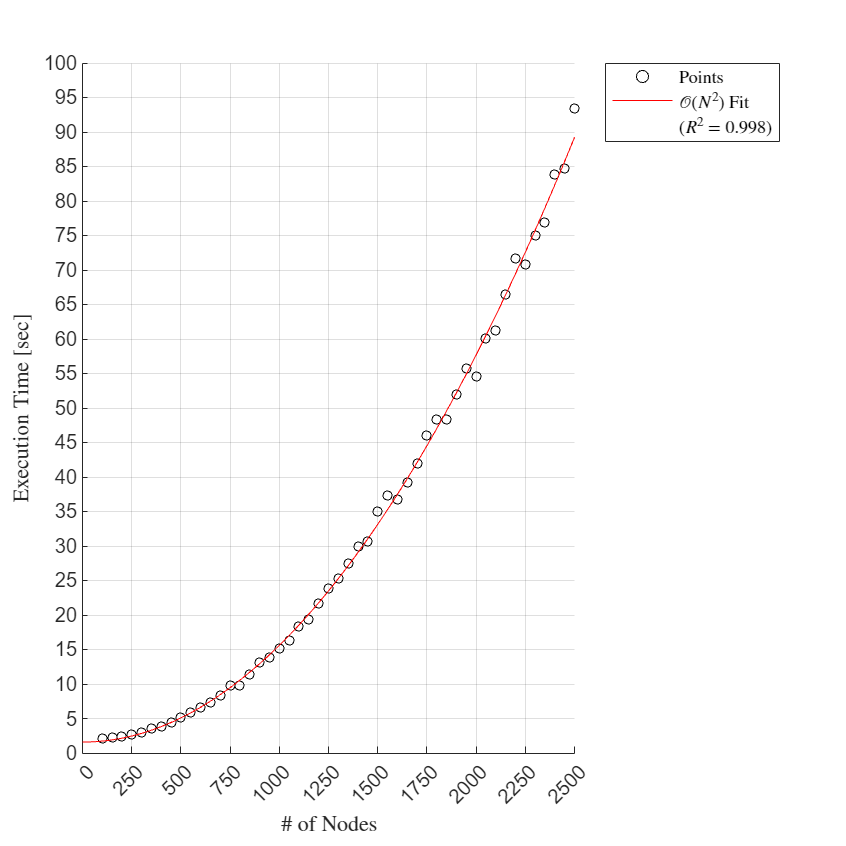

fg = figure('Position',[0,0,600,600]);
p1 = scatter(N_range, T,sz,'ko');
[cf,stats] = fit(N_range',T','a*x^2+b','StartPoint',[0 0]);
R2 = round(stats.rsquare,3);
hold on
p2 = plot(cf);
p3 = scatter(-1,-1,'white');
hold off

grid on
xticks(0:N_range(end)/10:N_range(end))
xlim([0,N_range(end)])
y_ = ylim();
y_(1) = 0;
ylim([y_(1),y_(2)]);
yticks(y_(1):5:y_(2))

xlabel("\# of Nodes","Interpreter","latex")
ylabel('Execution Time [sec]',"Interpreter","latex")

legend([p1,p2,p3],["Points","$\mathcal{O}(N^2)$ Fit","$(R^2="+string(R2)+")$"], ...
    "Location","northeastoutside",...
    "Interpreter","latex")

saveas(fg,"Time_Nodes.svg","svg");

N = N_chosen;
system("make main -f .\Makefile");

make: Nothing to be done for 'main'.


M = system(".\FiniteDifferences.exe " + string(N));
x = load(".\x.txt");

v1.x = round((131.25)/400 * N);
v1.y = round((125)/250 * M);
v2.x = round((400-131.25)/400 * N);
v2.y = round((125)/250 * M);

v3.x = round((151.39)/400 * N);
v3.y = round((250 - 76.39)/250 * M);
v4.x = round((400 - 151.39)/400 * N);
v4.y = round((76.39)/250 * M);
DV1 = abs(x(v1.x + N * (v1.y - 1)) - x(v2.x + N * (v2.y - 1))) * 1e6

DV1 = 58.7182

DV2 = abs(x(v3.x + N * (v3.y - 1)) - x(v4.x + N * (v4.y - 1))) * 1e6

DV2 = 38.6977

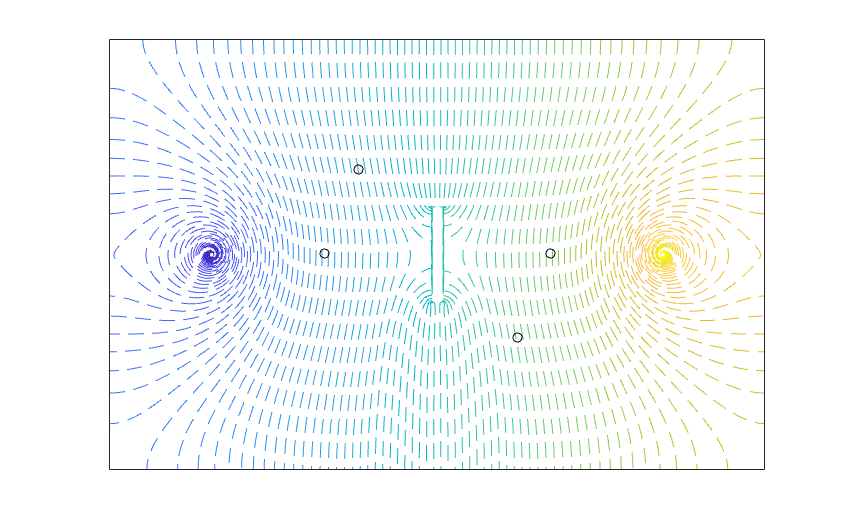


phi = zeros(M,N);
for i = 1:N
    for j = 1:M
        phi(j,i) = x(i + N * (j-1));
    end
end

fg = figure("Position",[0,0,800,500]);
X_range = linspace(0,4.0,size(phi,2));
Y_range = linspace(0,2.5,size(phi,1));
Dx = X_range(2) - X_range(1);
Dy = Y_range(2) - Y_range(1);
contour(X_range,Y_range,phi,120,'LineStyle',"--");
xlim([X_range(1), X_range(end)])
ylim([Y_range(1), Y_range(end)])
xticks(-1); yticks(-1);
hold on
sz = 20;
scatter(Dx*v1.x,Dy*v1.y,sz,'ko')
scatter(Dx*v2.x,Dy*v2.y,sz,'ko')
scatter(Dx*v3.x,Dy*v3.y,sz,'ko')
scatter(Dx*v4.x,Dy*v4.y,sz,'ko')
hold off
grid off
colormap();
saveas(fg,"Visual.svg","svg");